# DeepInterpolation - Tiny Ophys Inference Example

This example imports and uses a pre-trained DeepInterpolation model in MATLAB for inferring tiny ophys sample data.

## Initialize path

deepinterp.setup();

## Import and Assemble Model

The pre-trained network is available on an external file storage, as it is a bit larger (120 MB) than the other example networks. It is automatically downloaded by `deepinterp.sampleFile()` here. This is a file generated by the Keras package in Python.

modelFilename = deepinterp.sampleFile('2019_09_11_23_32_unet_single_1024_mean_absolute_error_Ai93-0450.h5');

Then import the trained model. Some warnings will be generated during the Keras import but they are not important.

deepinterpnet = deepinterp.Net.ImageTimeSeries('KerasFile','file',modelFilename);

## Import Sample TIFF Volume and normalize

ophys = single(tiffreadVolume('ophys_tiny_761605196.tif'));
[ophysNorm, C, S] = normalize(ophys,3,"center","mean","scale","std"); % where C = mean, S = std

## **Perform DeepInterpolation and undo normalization**

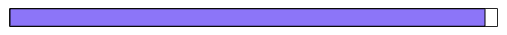

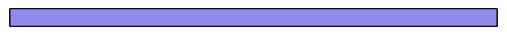

ophysInterpNorm = deepinterpnet.interp(ophysNorm,'progbar',1);

ophysInterp = ((ophysInterpNorm .* S)+C);

## Plot input and output

Show processed frames (from 31 ... 100-30 ).

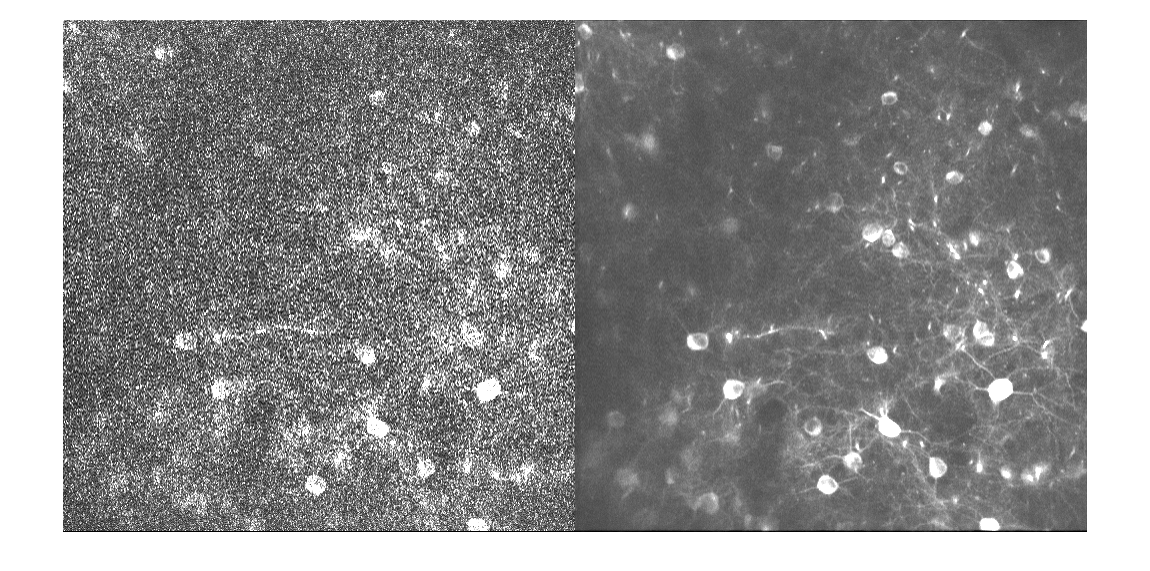

figure;
for idx = 31:size(ophys,3)-30
    imshow([ophys(:,:,idx) ophysInterp(:,:,idx)],...
        [0 prctile(ophys(:),95)]);  % scaling image to 0 .. 95 percentile to show range
    pause(0.1);
end
title("Input (left) and output (right) frames")